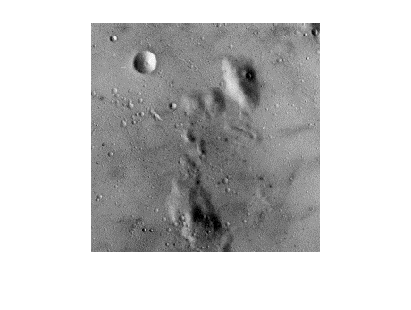



moon = imread("moon.jpg");
imshow(moon);

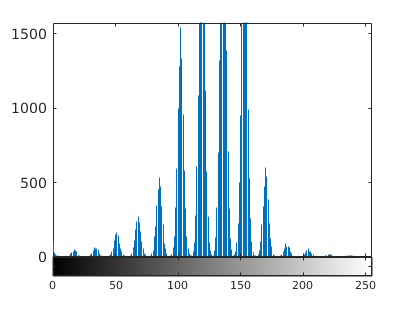



%Transforming into grayscale

gray_moon = rgb2gray(moon);
%imagesc((fftshift(abs(gray_moon_DFT))));

freq = zeros(256,1);
L = 0:255;
%Cumulative Distribution Function


[counts,bins]= imhist(gray_moon);
% imhist(gray_moon)

[height, width] = size(gray_moon);

%Find frequency of each intensity and pdf
for i = 1:height
    for j = 1:width
        for k = 1:256
            if gray_moon(i,j) == L(k)
                freq(k) = freq(k) + 1;         
            end
        end
    end
end

pdf = freq / (height*width);
%Find cdf
cdf = cumsum(pdf);
imhist(gray_moon);

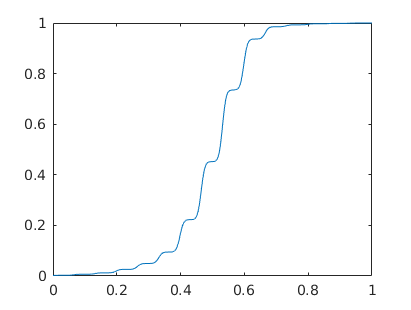

plot((0:255)/255,cdf)

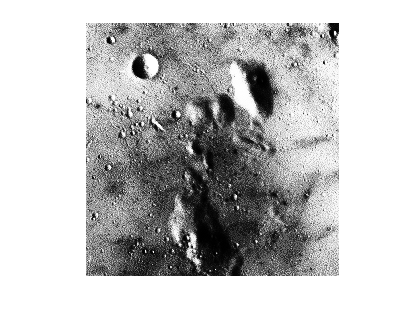

%Histogram Equalization
eq_hist = round(cdf * 255);
equalized_image = zeros(height,width);
%Mapping new gray level
for i = 1:height
    for j = 1:width
        equalized_image(i,j) = eq_hist(gray_moon(i,j)+1);
    end
end

%Final image
final_image = uint8(equalized_image);
imshow(final_image)

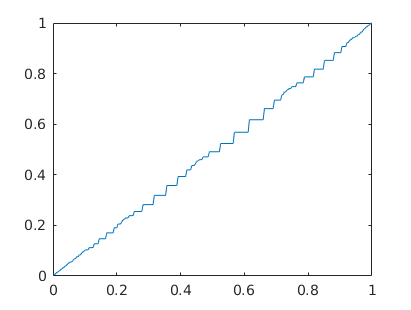

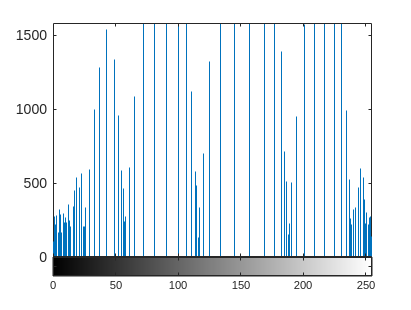


[final_counts, final_bins] = imhist(final_image);
final_cdf = cumsum(final_counts/(height*width));
imhist(final_image)
plot((0:255)/255,final_cdf)

%Change for github tutorial
